gtccLength = 18;
class1 = 'TURMER';
class2 = 'LUSMEG';

## Blackbird vs Nightingale binary SVM classification

baseFreqRange = [50 20000];
TURMER_gtcc = buildFeatureMatrix(class1,gtccLength,'train',false,baseFreqRange);
LUSMEG_gtcc = buildFeatureMatrix(class2,gtccLength,'train',false,baseFreqRange);

XTrain = [TURMER_gtcc;LUSMEG_gtcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_gtcc,1)) = -1;

gtccLinearSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

c = cvpartition(size(XTrain,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

## Testing PCA

TURMER_gtcc = buildFeatureMatrix(class1,gtccLength);
LUSMEG_gtcc = buildFeatureMatrix(class2,gtccLength);

XTrain = [TURMER_gtcc;LUSMEG_gtcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_gtcc,1)) = -1;

[XTrain95,coeffs95] = projectPCA(XTrain,95);

gtccLinearSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

c = cvpartition(size(XTrain95,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

### With 99% variance captured with PCA

[XTrain99,coeffs99] = projectPCA(XTrain,99);

gtccLinearSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

c = cvpartition(size(XTrain99,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

accuracyFullFreqRange = {};
test1 = buildFeatureMatrix(class1,gtccLength,'test');
test2 = buildFeatureMatrix(class2,gtccLength,'test');
testMatrix = {test1; test2};
testMatrix95 = {test1 * coeffs95; test2 * coeffs95};
testMatrix99 = {test1 * coeffs99; test2 * coeffs99};
testMatrices = {testMatrix;testMatrix95;testMatrix99};
modelsFull = {gtccLinearSvmTURMERxLUSMEG;gtccRBFSvmTURMERxLUSMEG};
models95 = {gtccLinearSvmTURMERxLUSMEG95;gtccRBFSvmTURMERxLUSMEG95};
models99 = {gtccLinearSvmTURMERxLUSMEG99;gtccRBFSvmTURMERxLUSMEG99};
models = {modelsFull;models95;models99};
for i = 1:3 % var
    for j = 1:2 % model type
        t1 = testMatrices{i}{1};
        t2 = testMatrices{i}{2};
        m = models{i}{j};
        acc1 = testModel(t1,-1,m);
        acc2 = testModel(t2,1,m);
        accuracyFullFreqRange{j,i} = [acc1,acc2];
    end
end

gtccTableFullFreqRange = table();
gtccTableFullFreqRange.('Full model') = accuracyFullFreqRange(:,1);
gtccTableFullFreqRange.('95% var PCA') = accuracyFullFreqRange(:,2);
gtccTableFullFreqRange.('99% var PCA') = accuracyFullFreqRange(:,3);
gtccTableFullFreqRange.Properties.RowNames = {'Linear','RBF'};

## Testing different frequency ranges

freqExperiment1Range = [500 12000];

TURMER_gtcc = buildFeatureMatrix(class1,gtccLength,'train',false,freqExperiment1Range);
LUSMEG_gtcc = buildFeatureMatrix(class2,gtccLength,'train',false,freqExperiment1Range);

XTrain = [TURMER_gtcc;LUSMEG_gtcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_gtcc,1)) = -1;

gtccLinearSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

c = cvpartition(size(XTrain,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

[~,coeffs95] = projectPCA(XTrain,95);

gtccLinearSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

c = cvpartition(size(XTrain95,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

[~,coeffs99] = projectPCA(XTrain,99);

gtccLinearSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);

c = cvpartition(size(XTrain99,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

accuracyFreqRangeExperiment1 = {};
test1 = buildFeatureMatrix(class1,gtccLength,'test',false,freqExperiment1Range);
test2 = buildFeatureMatrix(class2,gtccLength,'test',false,freqExperiment1Range);
testMatrix = {test1; test2};
testMatrix95 = {test1 * coeffs95; test2 * coeffs95};
testMatrix99 = {test1 * coeffs99; test2 * coeffs99};
testMatrices = {testMatrix;testMatrix95;testMatrix99};
modelsFull = {gtccLinearSvmTURMERxLUSMEG;gtccRBFSvmTURMERxLUSMEG};
models95 = {gtccLinearSvmTURMERxLUSMEG95;gtccRBFSvmTURMERxLUSMEG95};
models99 = {gtccLinearSvmTURMERxLUSMEG99;gtccRBFSvmTURMERxLUSMEG99};
models = {modelsFull;models95;models99};
for i = 1:3 % var
    for j = 1:2 % model type
        t1 = testMatrices{i}{1};
        t2 = testMatrices{i}{2};
        m = models{i}{j};
        acc1 = testModel(t1,-1,m);
        acc2 = testModel(t2,1,m);
        accuracyFreqRangeExperiment1{j,i} = [acc1,acc2];
    end
end

test1 = buildFeatureMatrix(class1,gtccLength,'test',false,freqExperiment1Range);
test2 = buildFeatureMatrix(class2,gtccLength,'test',false,freqExperiment1Range);

testModel(test2*coeffs95,1,gtccLinearSvmTURMERxLUSMEG95)

gtccTableFreqRangeExperiment1 = table();
gtccTableFreqRangeExperiment1.('Full model') = accuracyFreqRangeExperiment1(:,1);
gtccTableFreqRangeExperiment1.('95% var PCA') = accuracyFreqRangeExperiment1(:,2);
gtccTableFreqRangeExperiment1.('99% var PCA') = accuracyFreqRangeExperiment1(:,3);
gtccTableFreqRangeExperiment1.Properties.RowNames = {'Linear','RBF'};
gtccTableFreqRangeExperiment1

### Experiment 2: wider range (50-22050Hz)

freqExperiment2Range = [50 22050];

TURMER_gtcc = buildFeatureMatrix(class1,gtccLength,'train',false,freqExperiment2Range);
LUSMEG_gtcc = buildFeatureMatrix(class2,gtccLength,'train',false,freqExperiment2Range);

XTrain = [TURMER_gtcc;LUSMEG_gtcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_gtcc,1)) = -1;

gtccLinearSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

[~,coeffs95] = projectPCA(XTrain,95);
gtccLinearSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain95,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

[~,coeffs99] = projectPCA(XTrain,99);
gtccLinearSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain99,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

accuracyFreqRangeExperiment2 = {};
test1 = buildFeatureMatrix(class1,gtccLength,'test',false,freqExperiment2Range);
test2 = buildFeatureMatrix(class2,gtccLength,'test',false,freqExperiment2Range);
testMatrix = {test1; test2};
testMatrix95 = {test1 * coeffs95; test2 * coeffs95};
testMatrix99 = {test1 * coeffs99; test2 * coeffs99};
testMatrices = {testMatrix;testMatrix95;testMatrix99};
modelsFull = {gtccLinearSvmTURMERxLUSMEG;gtccRBFSvmTURMERxLUSMEG};
models95 = {gtccLinearSvmTURMERxLUSMEG95;gtccRBFSvmTURMERxLUSMEG95};
models99 = {gtccLinearSvmTURMERxLUSMEG99;gtccRBFSvmTURMERxLUSMEG99};
models = {modelsFull;models95;models99};
for i = 1:3 % var
    for j = 1:2 % model type
        t1 = testMatrices{i}{1};
        t2 = testMatrices{i}{2};
        m = models{i}{j};
        acc1 = testModel(t1,-1,m);
        acc2 = testModel(t2,1,m);
        accuracyFreqRangeExperiment2{j,i} = [acc1,acc2];
    end
end

gtccTableFreqRangeExperiment2 = table();
gtccTableFreqRangeExperiment2.('Full model') = accuracyFreqRangeExperiment2(:,1);
gtccTableFreqRangeExperiment2.('95% var PCA') = accuracyFreqRangeExperiment2(:,2);
gtccTableFreqRangeExperiment2.('99% var PCA') = accuracyFreqRangeExperiment2(:,3);
gtccTableFreqRangeExperiment2.Properties.RowNames = {'Linear','RBF'};
gtccTableFreqRangeExperiment2

fprintf('Accuracy for base frequency range (50-20000Hz)');

Accuracy for base frequency range (50-20000Hz)

gtccTableFullFreqRange

gtccTableFullFreqRange = 2×3 table
                 Full model           95% var PCA          99% var PCA   
              _________________    _________________    _________________

    Linear    {[0.6718 0.8553]}    {[0.4419 0.9455]}    {[0.4238 0.9624]}
    RBF       {[0.2429 0.9962]}    {[0.2403 0.9925]}    {[0.2300 0.9906]}


fprintf('Accuracy for limited frequency range (500-12000Hz)');

Accuracy for limited frequency range (500-12000Hz)

gtccTableFreqRangeExperiment1

gtccTableFreqRangeExperiment1 = 2×3 table
                 Full model           95% var PCA          99% var PCA   
              _________________    _________________    _________________

    Linear    {[0.6951 0.7726]}    {[0.4548 0.9455]}    {[0.4238 0.9624]}
    RBF       {[0.7804 0.6579]}    {[0.6279 0.6767]}    {[0.6460 0.6447]}


fprintf('Accuracy for extended frequency range (50-22050Hz)');

Accuracy for extended frequency range (50-22050Hz)

gtccTableFreqRangeExperiment2

gtccTableFreqRangeExperiment2 = 2×3 table
                 Full model           95% var PCA          99% var PCA   
              _________________    _________________    _________________

    Linear    {[0.6796 0.8609]}    {[0.4548 0.9455]}    {[0.4238 0.9624]}
    RBF       {[0.8062 0.6222]}    {[0.7132 0.5996]}    {[0.6873 0.6241]}


### Experiment 3: full range (50-fs/2)

This is the default behaviour of gtcc

TURMER_gtcc = buildFeatureMatrix(class1,gtccLength);
LUSMEG_gtcc = buildFeatureMatrix(class2,gtccLength);

XTrain = [TURMER_gtcc;LUSMEG_gtcc];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(TURMER_gtcc,1)) = -1;

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.2488 |      36.477 |      0.2488 |      0.2488 |      0.13535 |       13.506 |
|    2 | Accept |      0.4732 |      40.624 |      0.2488 |     0.26219 |      0.12335 |    0.0036528 |
|    3 | Accept |     0.25704 |      27.129 |      0.2488 |     0.24882 |       141.93 |       371.89 |
|    4 | Accept |      0.4732 |      37.917 |      0.2488 |     0.24883 |       194.53 |    0.0015001 |
|    5 | Accept |      0.4378 |       52.91 |      0.2488 |     0.32104 |    0.0048232 |       56.119 |
|    6 | Accept |     0.24948 |       40.72 |      0.2488 |     

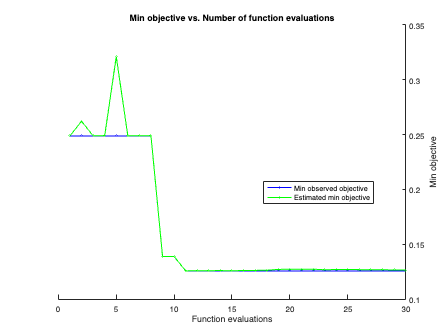

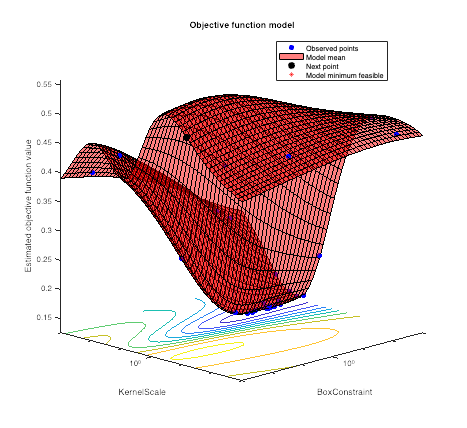


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 954.2405 seconds
Total objective function evaluation time: 905.8913

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

        255.1          13.718   

Observed objective function value = 0.12577
Estimated objective function value = 0.12768
Function evaluation time = 24.7361

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       113.77          12.532   

Estimated objective function value = 0.12657
Estimated function evaluation time = 24.9441



gtccRBFSvmTURMERxLUSMEG =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1532×1 double]
                                 Bias: 0.1231
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


gtccLinearSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG = fitcsvm(XTrain,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

[XTrain95,coeffs95] = projectPCA(XTrain,95);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.4732 |      7.2505 |      0.4732 |      0.4732 |    0.0071817 |    0.0047848 |
|    2 | Best   |     0.35223 |      2.0416 |     0.35223 |     0.35833 |      0.11578 |        591.2 |
|    3 | Accept |      0.4732 |      1.3457 |     0.35223 |     0.36363 |    0.0062289 |        2.557 |
|    4 | Best   |     0.28351 |      2.3962 |     0.28351 |     0.28351 |       151.04 |       63.424 |
|    5 | Best   |     0.25533 |      2.1804 |     0.25533 |     0.25534 |        11.07 |       5.0904 |
|    6 | Accept |     0.26942 |      1.4247 |     0.25533 |     

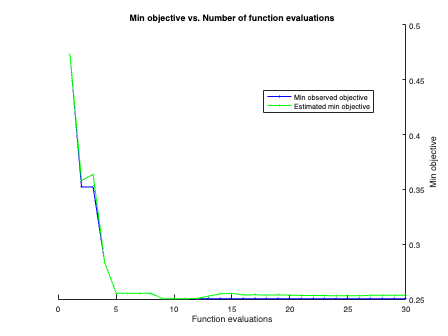

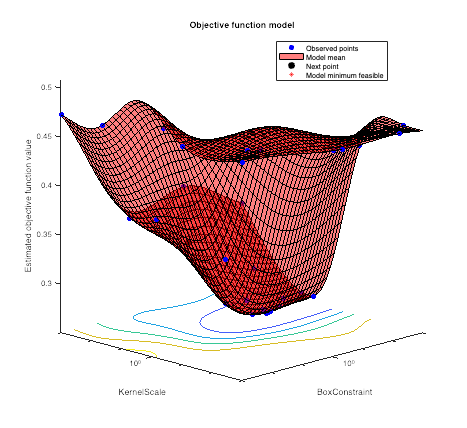


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 567.2207 seconds
Total objective function evaluation time: 527.5427

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       53.907          8.7656   

Observed objective function value = 0.25052
Estimated objective function value = 0.25563
Function evaluation time = 3.0787

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       31.748          4.9074   

Estimated objective function value = 0.25374
Estimated function evaluation time = 4.3052



gtccRBFSvmTURMERxLUSMEG95 =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1626×1 double]
                                 Bias: 0.0901
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


gtccLinearSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain95,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG95 = fitcsvm(XTrain95,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

[XTrain99,coeffs99] = projectPCA(XTrain,99);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.4732 |      1.9029 |      0.4732 |      0.4732 |    0.0027281 |      0.77421 |
|    2 | Best   |     0.45498 |      2.9143 |     0.45498 |      0.4559 |       435.38 |    0.0099499 |
|    3 | Best   |     0.35223 |      1.5781 |     0.35223 |     0.35224 |      0.03609 |       894.51 |
|    4 | Best   |      0.2701 |      3.2758 |      0.2701 |     0.27982 |        119.1 |       22.053 |
|    5 | Accept |     0.27216 |       3.854 |      0.2701 |     0.27019 |       171.89 |       24.799 |
|    6 | Accept |       0.311 |       1.425 |      0.2701 |     

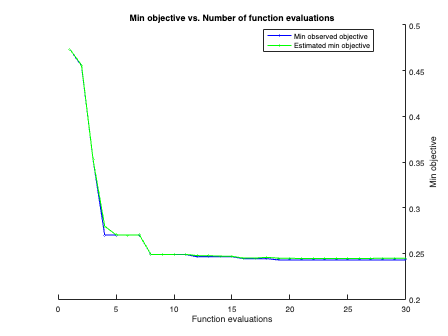


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 481.8504 seconds
Total objective function evaluation time: 450.0243

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       313.87          8.5926   

Observed objective function value = 0.24296
Estimated objective function value = 0.24484
Function evaluation time = 10.4972

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       313.87          8.5926   

Estimated objective function value = 0.24484
Estimated function evaluation time = 11.5263



gtccRBFSvmTURMERxLUSMEG99 =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2910
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1508×1 double]
                                 Bias: 1.2530
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2910×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2910×1 logical]
                               Solver: 'SMO'


  Properties, Methods


gtccLinearSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','linear',...
    'Standardize',true,'ClassNames',[-1,1]);
c = cvpartition(size(XTrain99,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
gtccRBFSvmTURMERxLUSMEG99 = fitcsvm(XTrain99,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

accuracyFreqRangeExperiment3 = {};
TURMER_gtccTest = buildFeatureMatrix(class1,gtccLength,'test');
LUSMEG_gtccTest = buildFeatureMatrix(class2,gtccLength,'test');
testMatrix = {TURMER_gtccTest; LUSMEG_gtccTest};
testMatrix95 = {TURMER_gtccTest * coeffs95; LUSMEG_gtccTest * coeffs95};
testMatrix99 = {TURMER_gtccTest * coeffs99; LUSMEG_gtccTest * coeffs99};
testMatrices = {testMatrix;testMatrix95;testMatrix99};
modelsFull = {gtccLinearSvmTURMERxLUSMEG;gtccRBFSvmTURMERxLUSMEG};
models95 = {gtccLinearSvmTURMERxLUSMEG95;gtccRBFSvmTURMERxLUSMEG95};
models99 = {gtccLinearSvmTURMERxLUSMEG99;gtccRBFSvmTURMERxLUSMEG99};
models = {modelsFull;models95;models99};
for i = 1:3 % var
    for j = 1:2 % model type
        t1 = testMatrices{i}{1};
        t2 = testMatrices{i}{2};
        m = models{i}{j};
        acc1 = testModel(t1,-1,m);
        acc2 = testModel(t2,1,m);
        accuracyFreqRangeExperiment3{j,i} = [acc1,acc2];
    end
end

gtccTableFreqRangeExperiment3 = table();
gtccTableFreqRangeExperiment3.('Full model') = accuracyFreqRangeExperiment3(:,1);
gtccTableFreqRangeExperiment3.('95% var PCA') = accuracyFreqRangeExperiment3(:,2);
gtccTableFreqRangeExperiment3.('99% var PCA') = accuracyFreqRangeExperiment3(:,3);
gtccTableFreqRangeExperiment3.Properties.RowNames = {'Linear','RBF'};
% gtccTableFreqRangeExperiment3

# ----- Helper Functions -----

function featureMatrix = buildFeatureMatrix(birdID,gtccLength,type,sampleLimit,freqRange)
arguments
birdID
gtccLength = 18
type = 'train'
sampleLimit = false
freqRange = false
end
directoryPath = sprintf('samples/%s/syllables/%s',birdID,type);
fileList = dir(fullfile(directoryPath, '*.wav'));
if sampleLimit
    limit = sampleLimit;
else
    limit = numel(fileList);
end
featureMatrix = zeros(limit,gtccLength*14*3);
for ii = 1:limit
    filePath = fullfile(directoryPath, fileList(ii).name);
    [syllable, fs] = audioread(filePath);
    if freqRange 
        featureMatrix(ii,:) = extractGtcc(syllable,fs,gtccLength,freqRange);
    else
        featureMatrix(ii,:) = extractGtcc(syllable,fs,gtccLength);
    end
end
end